# MACHINE LEARNING CLASSIFICATION USED TO PREDICT STOCK PRICE

Kevin Chng

Application Engineer

kevinchng@techsource-asia.com

## Overview :

        In this script, it use Machine Learning in MATLAB to forecast Stock Price. Using real life data, it will explore how to manage time-stamped data and select the best fit machine learning model. As common being widely known, preparing data and select the significant features play big role in the accuracy of model. In this example, it uses the technical indicators of today to predict the next day stock close price. 

        In this example, the trading strategy is if the close price is higher 1% than the open price in the same day, then we should buy stock at the openning of the stock market and sell it at the closing of the stock market.

       In this example, it demostrates how to pre-processing the data for modelling and predict the decision by the model. New data of each date will be tabulated to re-train new model and find the best model for next day prediction. Interesting?

[Note : Not advocating any particular strategy, factors or methodology]

## **Highlights : **

- Handling downloaded data from Yahoo Finance using the timetable object

- Selecting features based on domain knowledge

- Machine Learning Modeling

- Automate to re-train new model to incorproate new updated data for next prediction

- Predicting the buying-decision

- Experience the computational speed with/without parallel computing

## **Product Focus :**

- MATLAB

- Financial Toolbox

- Statistics and Machine Learning Toolbox

- Parallel Computing Toolbox

## **Flow :**

**Written at 21 August 2018**

clc;
clear all;

## **Activate Parallel Computing**

You may decide to run the example with/without parallel computing and experience the difference in computational speed.

parallelcomputing = false; %true is on %false is off
if parallelcomputing ==true
    parpool(4);
else
    delete(gcp('nocreate'))
end

## Load the Stock Data & Pre-processing them

In this part, you may either download the stock data via yahoo finance or read the stock data from csv. file (it is also downloaded from Yahoo Finance).

if you want to select your own stock and download the data via Yahoo finance, you may set the command below to 'false', else left it as 'true' to read the stock data from the csv. file.

UseDefaultData = true;

The function (getMarketDataViaYahoo) is downloaded from the link below:

[https://www.mathworks.com/matlabcentral/fileexchange/68361-yahoo-finance-data-downloader](https://www.mathworks.com/matlabcentral/fileexchange/68361-yahoo-finance-data-downloader) 

% Example: 

 data = getMarketDataViaYahoo('Your Stock Name in Yahoo Finance', '1-Jan-2018', datetime('today'));

warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
if UseDefaultData == true
StockData = readtable('5099.KL.csv','ReadVariableNames',true);    
else
StockData = getMarketDataViaYahoo('5099.KL', '1-July-2013', '31-July-2018');
end

Other than importing your excel data or read the data from Yahoo Finance, there are datafeed toolbox and database toolbox allowing users to fetching data from various financial data platform (Bloomberg, Reuters, Thomson,Havar Analytica and etc) and various database platform (Ms. Access, SQL, SQLite and etc).

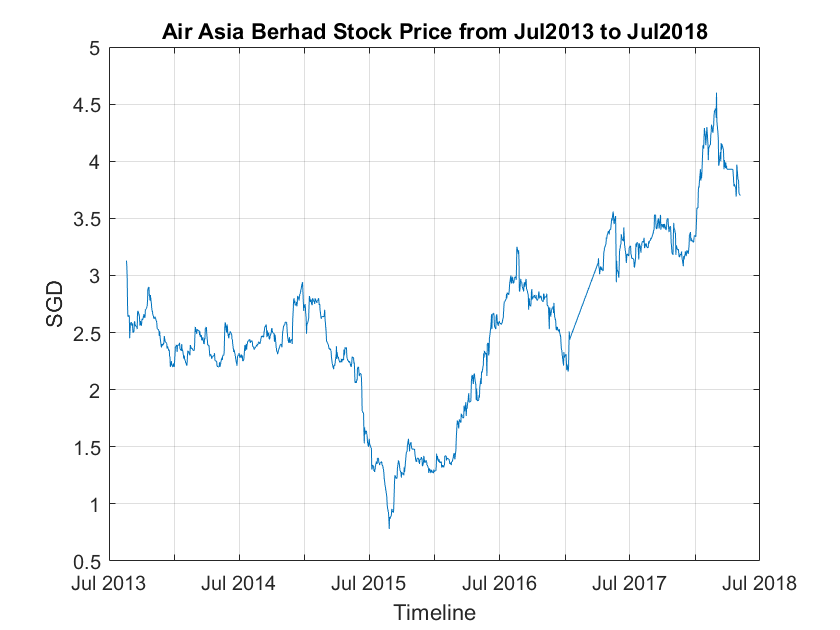

warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');

%Ensure the data is in correct data type
if isnumeric(StockData.Open) == false
    Open =cellfun(@str2double,StockData.Open);
    High = cellfun(@str2double,StockData.High);
    Low = cellfun(@str2double,StockData.Low);
    Close = cellfun(@str2double,StockData.Close);
    AdjustedClose = cellfun(@str2double,StockData.AdjClose);
    Volume = cellfun(@str2double,StockData.Volume);
else
    Open = StockData.Open;
    High = StockData.High;
    Low = StockData.Low;
    Close = StockData.Close;
    AdjustedClose = StockData.AdjClose;
    Volume =  StockData.Volume;
end
Date = StockData.Date;

%Tranform the data to timetable
StockData_TimeTable = timetable(Date,Open,High,Low,Close,Volume);

%Check for missing Data
%Fill the missing data with linear
if any(any(ismissing(StockData_TimeTable)))==true
    StockData_TimeTable = fillmissing(StockData_TimeTable,'linear');
end

%Delete the row if volume is 0
StockData_TimeTable(StockData_TimeTable.Volume==0,:) =[];

%View the data
plot(StockData_TimeTable.Date,StockData_TimeTable.Close);
title('Air Asia Berhad Stock Price from Jul2013 to Jul2018');
ylabel('SGD');
xlabel('Timeline');
grid on

## Selecting Features based on Domain Knowledge & Classify the DataSet (Buy/Not Buy)

Features will decide the accuracy of model, therefore it is always important to select the correct and significant features to train the model. In our example, we are not advocating any particular strategy, factors or methodology, therefore, we will only use technical indicators to train our model. It will be more interesting if you incorprate other social factors (sentiment result of news through text analytic, fundamental indicators and etc)

In this part, we will code that if the close price higher 1% than the open price at the same day, then we will buy the stock else we don't buy the stock. As mentioned, ur trading strategy here is to buy the stock at the openning of market and then sell the stock at the closing of market.

Year 2015 will be selected as train data used to predict the stock price in Year 2016.

%Extract Technical Indicators
%Relative Strength Index 1st-3th Features
rsi7 = rsindex(StockData_TimeTable.Close,'WindowSize',7);
rsi14 = rsindex(StockData_TimeTable.Close,'WindowSize',14);
rsi21 = rsindex(StockData_TimeTable.Close,'WindowSize',21);
%Moving Average 3th - 6th Features
EMA3 = movavg(StockData_TimeTable.Close,'linear',3);
EMA5 = movavg(StockData_TimeTable.Close,'linear',5);
EMA10 = movavg(StockData_TimeTable.Close,'linear',10);
%Exponential Moving Average 7 Feature
EXPMOV7 = movavg(StockData_TimeTable.Close,'exponential',7);
%Moving Average Convergent/Divergent 8-9th Features
[MACDLine, signalLine]= macd(StockData_TimeTable.Close);
%Negative Volume Index 10th Features
NVIind = negvolidx(StockData_TimeTable);
%Positive Volume Index 11th Features
PosVind = posvolidx(StockData_TimeTable);
%Accumulation/Distribution OSciallator 12th Features
ADOsc = adosc(StockData_TimeTable);
%Time Series Bollinger band 13-15 Features
[middle,upper,lower] = bollinger(StockData_TimeTable);
%Highest high 16 Features
highind = hhigh(StockData_TimeTable) ;
%Lowest low 17 Features
lowind = llow(StockData_TimeTable);
%Median Price 18 Features
MedIdx = medprice(StockData_TimeTable);
%on-balance volume 19 Features
volumeIdx = onbalvol(StockData_TimeTable);
%Price and Volume Trend(PVT) 20 Features
pvtInd = pvtrend(StockData_TimeTable); 
%williams Accumulation/Distribution line 21 Features
willadidx = willad(StockData_TimeTable);
%Ticket Return Series 22 Features
tick2retidx = tick2ret(StockData_TimeTable);
%Chaikin Volatility 23
volatility = chaikvolat(StockData_TimeTable);
%Stochastic Oscillator 24
percentKnD = stochosc(StockData_TimeTable);
%Acceleration between times 25
acceleration = tsaccel(StockData_TimeTable);
%Momentum between times 26
momentum = tsmom(StockData_TimeTable);


%As explained, price today will be used to predict the stock price tomorrow. Hence all the indicators move forward 1 date.
% Only Open price of stock will be considered as feature as it is the only price we know before opening market in the day.
% 1st data point will be removed as there does not have any value for their feature indicators.
PredictionTable = timetable(StockData_TimeTable.Date(2:end),rsi7(1:end-1),rsi14(1:end-1),rsi21(1:end-1),...
    EMA3(1:end-1),EMA5(1:end-1),EMA10(1:end-1),EXPMOV7(1:end-1),MACDLine(1:end-1),signalLine(1:end-1),NVIind.NegativeVolume(1:end-1),PosVind.PositiveVolume(1:end-1),ADOsc.ADOscillator(1:end-1),...
    middle.Open(1:end-1),upper.Open(1:end-1),lower.Open(1:end-1),highind.HighestHigh(1:end-1),...
    lowind.LowestLow(1:end-1),MedIdx.MedianPrice(1:end-1),pvtInd.PriceVolumeTrend(1:end-1),...
    volumeIdx.OnBalanceVolume(1:end-1), willadidx.WillAD(1:end-1), tick2retidx.Open(1:end),...
    volatility.ChaikinVolatility(1:end-1),percentKnD.FastPercentK(1:end-1),acceleration.Open(1:end-1),...
    momentum.Open(1:end-1),StockData_TimeTable.Open(2:end));

% get Year 2016 data out for training
tr = timerange('2015-01-01' , '2015-12-31');
PredictionTable_2015 = PredictionTable(PredictionTable.Time(tr),:);

% get 2H Year 2017 data out for prediction
tr = timerange('2016-01-01' , '2016-12-31');
PredictionTable_2016 = PredictionTable(PredictionTable.Time(tr),:);

% Deal with missing data
PredictionTable_2015(any(ismissing(PredictionTable_2015),2),:)=[];
PredictionTable_2016(any(ismissing(PredictionTable_2016),2),:)=[];

% Get the Open and Close Price Data for year 2016 & 2017
OpenClose_2015 = StockData_TimeTable(PredictionTable_2015.Time,:);
OpenClose_2016 = StockData_TimeTable(PredictionTable_2016.Time,:);

% In this strategy, it consider worth to buy the stock or not if we buy the stock at market open rate and sell out at the end of the day
% We does not know the close rate, but we will know the open rate before prediction.
% if the close rate higher than open rate more than 1%, then we classify it as 'buy' in our original data.

for i =1:height(OpenClose_2015)
if OpenClose_2015.Open(i)*1.01 < OpenClose_2015.Close(i)
    Response2015(i)="buy";
else 
    Response2015(i)="Not buy";
end
end

Response2015=categorical(Response2015);
Categ=categories(Response2015)

Categ = 2×1 cell array
    {'Not buy'}
    {'buy'    }


nnz(Response2015=="buy")

ans = 51

nnz(Response2015=="Not buy")

ans = 194

for i =1:height(OpenClose_2016)
if OpenClose_2016.Open(i)*1.01 < OpenClose_2016.Close(i)
    Response2016(i)="buy";
else 
    Response2016(i)="Not buy";
end
end

Response2016=categorical(Response2016);
categories(Response2016)

ans = 2×1 cell array
    {'Not buy'}
    {'buy'    }


nnz(Response2016=="buy")

ans = 65

nnz(Response2016=="Not buy")

ans = 180

## Normalize the features

To overcome the model learning problem, we normalize the data. Therefore, the gradient descents can converge more quickly. It might generate a model with higher accuracy if you normalize your data, it will elimate the bias of model toward to the feature with larger numeric value.

PredictionTable_2015 = normalize(PredictionTable_2015);
PredictionTable_2016 = normalize(PredictionTable_2016);

## **Machine Learning Modelling**

Year 2015 will be used to train the machine learning modelling. However, the model here will only used to predict the frst trading day in year 2016. New model will be trained to incorprate the first trading day data and it used to predict the second trading day in year 2016.

Therefore, we will always to re-train new model for next prediction. You may refer to back-testing section later to see how this example automate the re-train model part.

If you have parallel computing toolbox, you may use parfor to train multiple model at same time.

%add path to folder consisting modelling code
currentdirectory = pwd;
fileread=strcat(currentdirectory,'\models');
addpath(fileread);

% Convert Timestable to table
PredictionTable_2015_Table = timetable2table(PredictionTable_2015);
PredictionTable_2015_Table.Response=Response2015';
PredictionTable_2016_Table = timetable2table(PredictionTable_2016);
PredictionTable_2016_Table.Response=Response2016';

% Train Model, we are not seeking to deal with the features in order to improve the accuracy
%Fine Tree Model
[Model(1), validationAccuracy(1),validationPred{1}] = FineTree(PredictionTable_2015_Table);
ModelName(1) = "Fine Tree";
%Medium Tree Model
[Model(2), validationAccuracy(2),validationPred{2}] = MediumTree(PredictionTable_2015_Table);
ModelName(2) = "Medium Tree";
%Course Tree Model
[Model(3), validationAccuracy(3),validationPred{3}] = CourseTree(PredictionTable_2015_Table);
ModelName(3) = "Course Tree";
%Linear Discriminant Model
[Model(4), validationAccuracy(4),validationPred{4}] = LinearDiscriminant(PredictionTable_2015_Table);
ModelName(4) = "Linear Discriminant";
%Linear SVM
[Model(5), validationAccuracy(5),validationPred{5}] = LinearSVM(PredictionTable_2015_Table);
ModelName(5) = "Linear SVM";
%Quadratic SVM
[Model(6), validationAccuracy(6),validationPred{6}] = QuadraticSVM(PredictionTable_2015_Table);
ModelName(6) = "Quadratic SVM";
%Cubic SVM
[Model(7), validationAccuracy(7),validationPred{7}] = CubicSVM(PredictionTable_2015_Table);
ModelName(7) = "Cubic SVM";
%Fine Gaussian SVM
[Model(8), validationAccuracy(8),validationPred{8}] = FineGaussianSVM(PredictionTable_2015_Table);
ModelName(8) = "Fine Gaussian SVM";
%Medium Gaussian SVM
[Model(9), validationAccuracy(9),validationPred{9}] = MediumGaussianSVM(PredictionTable_2015_Table);
ModelName(9) = "Medium Gaussian SVM";
%Course Gaussian SVM
[Model(10), validationAccuracy(10),validationPred{10}] = CourseGaussianSVM(PredictionTable_2015_Table);
ModelName(10) = "Course Gaussian SVM";
%Fine KNN
[Model(11), validationAccuracy(11),validationPred{11}] = FineKNN(PredictionTable_2015_Table);
ModelName(11) = "Fine KNN";
%Medium KNN
[Model(12), validationAccuracy(12),validationPred{12}] = MediumKNN(PredictionTable_2015_Table);
ModelName(12) = "Medium KNN";
%Coarse KNN
[Model(13), validationAccuracy(13),validationPred{13}] = CoarseKNN(PredictionTable_2015_Table);
ModelName(13) = "Course KNN";
%Cosine KNN
[Model(14), validationAccuracy(14),validationPred{14}] = CosineKNN(PredictionTable_2015_Table);
ModelName(14) = "Cosine KNN";
%Cubic KNN
[Model(15), validationAccuracy(15),validationPred{15}] = CubicKNN(PredictionTable_2015_Table);
ModelName(15) = "Cubic KNN";
%Weighted KNN
[Model(16), validationAccuracy(16),validationPred{16}] = WeightedKNN(PredictionTable_2015_Table);
ModelName(16) = "Weighted KNN";
%Ensemble Boosted KNN
[Model(17), validationAccuracy(17),validationPred{17}] = EnsembleBoostedTree(PredictionTable_2015_Table);
ModelName(17) = "Ensemble Boosted Tree";
%Ensemble Bagged KNN
[Model(18), validationAccuracy(18),validationPred{18}] = EnsembleSubspaceDiscriminant(PredictionTable_2015_Table);
ModelName(18) = "Ensemble Subspace Discriminant";
%Ensemble Subspace KNN
[Model(19), validationAccuracy(19),validationPred{19}] = EnsembleSubspaceKNN(PredictionTable_2015_Table);
ModelName(19) = "Ensemble Subspace KNN";
%Ensemble RUSBoosted Trees KNN
[Model(20), validationAccuracy(20),validationPred{20}] = EnsembleRUSBoostedTrees(PredictionTable_2015_Table);
ModelName(20) = "Ensemble RUS Boosted Trees";

The trainning model above will be saved in function TRAINING MODEL. Therefore, for any new update, the model will incorporate the new data and re-train the model for next prediction.

## **Select the best Model Based on Strategy**

In previous vesion of this example, I used in-sample data (Year2015) accuracy to decide which one is the best model (refer to the code below).

*BestModelNo =  1;*

*for i =2:1:20*

*    %compare the accuracy of different model*

*    if validationAccuracy(i)>validationAccuracy(i-1)*

*        BestModelNo = i;*

*    end   *

*end*

Now, I changed to use **'earn> lost' strategy** to decide which one is the best model. **What does it mean?**

Actual - Buy, Prediction - Don't Buy (Nothing Happen)

Actual - Buy, Prediction - Buy (Earn Money)

Actual - Don't buy, Prediction - Don't buy (Nothing Happen)

Actual - Don't buy, Prediction - Buy (Lost Money)

Therefore, i will choose the model that has earn>lost.

[I'm still thinking to best way to set the strategy, Year 2015 is in-sample data, it would be better if you use out-sample data for validation]

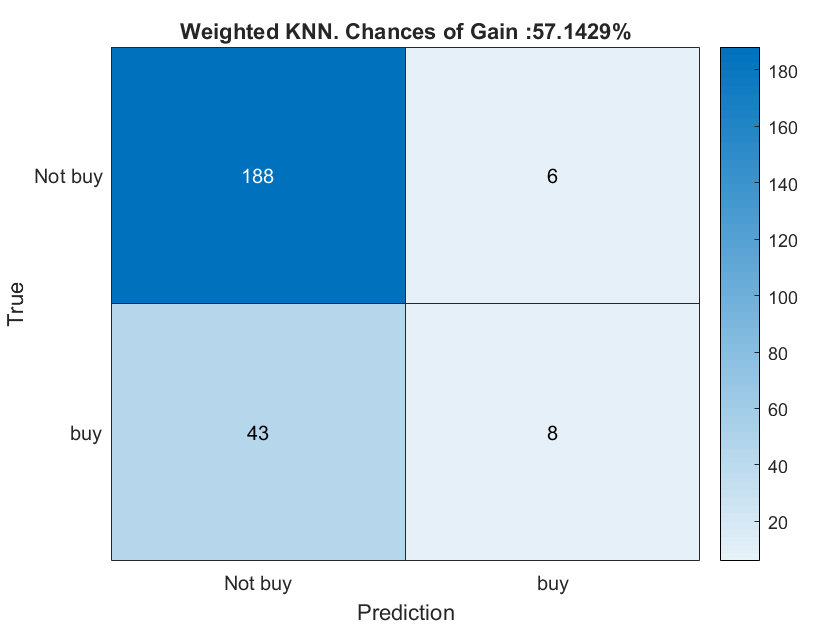

BestModelNo = 1;
for i =1:1:20
    
    earn = sum(validationPred{i}(Response2015 =='buy')=='buy');
    lost = sum(validationPred{i}(Response2015 =='Not buy') == 'buy');
    
    gain = earn-lost;
    if i ==1
        indicator =gain;
    elseif gain>indicator
        BestModelNo=i;
        indicator = gain;
        percentage = earn/(earn+lost);
    end
end

%Display the best model
confmat=confusionmat(Response2015,validationPred{BestModelNo});
heatmap(Categ,Categ,confmat);
titlecnf=strcat(ModelName(BestModelNo),'. Chances of Gain : ',num2str(percentage*100),'%');
title(titlecnf);
ylabel('True')
xlabel('Prediction')

## **BackTesting - First Prediction**

We use the trained model in previous section to predict the first trading day decision in year 2016. The result is save in table- resulttable.

ModelPrediction = Model(BestModelNo);
ModelNameFinal = ModelName(BestModelNo);
Model_Accuracy=validationAccuracy(BestModelNo);

% predict for first trading day of 2016 before stock market open
predictionoutcome=ModelPrediction.predictFcn(PredictionTable_2016_Table(1,:));

% save our result in result table
% time, stock open price,stock close price, true result, prediction result,model,accuracy
resulttable = table(OpenClose_2016.Date(1),OpenClose_2016.Open(1),OpenClose_2016.Close(1),Response2016(1),predictionoutcome,ModelNameFinal,Model_Accuracy);
resulttable.Properties.VariableNames(1)={'Date'};
resulttable.Properties.VariableNames(1)={'Open'};
resulttable.Properties.VariableNames(1)={'Close'};
resulttable

resulttable = 1×7 table
      Close       Var2    Var3     Var4      predictionoutcome    ModelNameFinal    Model_Accuracy
    __________    ____    ____    _______    _________________    ______________    ______________

    2016-01-04    1.28    1.29    Not buy         Not buy         "Weighted KNN"         0.8      


## **BackTesting - To Predict the First 15 trading days in year 2016**

In this part, we will automate to update the new modelling with new updated data of each day to predict the next trading day decision. The final result will be saved in table - resulttable.

% update the table and re-train the model for next prediction
% keep them into for loop to predict the first 30 days of trading day in year 2017
% since first day is predicted, therefore we need to predict the next 29 days

for i=1:1:14
tableprediction = [PredictionTable_2015_Table;PredictionTable_2016_Table(i,:)];
%trainmodelwithnewupdate
[ModelPrediction,ModelNameFina,Model_Accuracy] = MachineLearningModellingNewUpdate(tableprediction) ;
% predict for first trading day of 2016 before stock market open
predictionoutcome=ModelPrediction.predictFcn(PredictionTable_2016_Table(i+1,:));
Newresult=table(OpenClose_2016.Date(i+1),OpenClose_2016.Open(i+1),OpenClose_2016.Close(i+1),Response2016(i+1),predictionoutcome,ModelNameFinal,Model_Accuracy);
Newresult.Properties.VariableNames(1)={'Date'};
Newresult.Properties.VariableNames(1)={'Open'};
Newresult.Properties.VariableNames(1)={'Close'};
resulttable= [resulttable;Newresult];
end

## **Conclusion**

Artificial Intelligent (AI), the buzzword of the year, has been raising up eyeballs in financial industry. I hope this example can give you some insight on how AI is transforming finance. Accuracy is not main concern in this example as we are not advocating any strategy or method in trading. Enjoy!

% Result
display(resulttable);

resulttable = 15×7 table
      Close       Var2    Var3     Var4      predictionoutcome    ModelNameFinal    Model_Accuracy
    __________    ____    ____    _______    _________________    ______________    ______________

    2016-01-04    1.28    1.29    Not buy         Not buy         "Weighted KNN"           0.8    
    2016-01-05    1.28    1.34    buy             Not buy         "Weighted KNN"       0.79268    
    2016-01-06    1.33    1.44    buy             Not buy         "Weighted KNN"       0.78862    
    2016-01-07    1.44    1.39    Not buy         Not buy         "Weighted KNN"       0.79268    
    2016-01-08    1.37    1.42    buy             Not buy         "Weighted KNN"       0.79268    
    2016-01-11    1.41    1.37    Not buy  

## **Helper Function - MACHINE LEARNING MODELLING**

function [ModelPrediction,ModelName,Model_Accuracy] = MachineLearningModellingNewUpdate(tableprediction) 


% Train Model, we are not seeking to deal with the features in order to improve the accuracy
%Fine Tree Model
[Model(1), validationAccuracy(1),validationPred{1}] = FineTree(tableprediction);
ModelName(1) = "Fine Tree";
%Medium Tree Model
[Model(2), validationAccuracy(2),validationPred{2}] = MediumTree(tableprediction);
ModelName(2) = "Medium Tree";
%Course Tree Model
[Model(3), validationAccuracy(3),validationPred{3}] = CourseTree(tableprediction);
ModelName(3) = "Course Tree";
%Linear Discriminant Model
[Model(4), validationAccuracy(4),validationPred{4}] = LinearDiscriminant(tableprediction);
ModelName(4) = "Linear Discriminant";
%Linear SVM
[Model(5), validationAccuracy(5),validationPred{5}] = LinearSVM(tableprediction);
ModelName(5) = "Linear SVM";
%Quadratic SVM
[Model(6), validationAccuracy(6),validationPred{6}] = QuadraticSVM(tableprediction);
ModelName(6) = "Quadratic SVM";
%Cubic SVM
[Model(7), validationAccuracy(7),validationPred{7}] = CubicSVM(tableprediction);
ModelName(7) = "Cubic SVM";
%Fine Gaussian SVM
[Model(8), validationAccuracy(8),validationPred{8}] = FineGaussianSVM(tableprediction);
ModelName(8) = "Fine Gaussian SVM";
%Medium Gaussian SVM
[Model(9), validationAccuracy(9),validationPred{9}] = MediumGaussianSVM(tableprediction);
ModelName(9) = "Medium Gaussian SVM";
%Course Gaussian SVM
[Model(10), validationAccuracy(10),validationPred{10}] = CourseGaussianSVM(tableprediction);
ModelName(10) = "Course Gaussian SVM";
%Fine KNN
[Model(11), validationAccuracy(11),validationPred{11}] = FineKNN(tableprediction);
ModelName(11) = "Fine KNN";
%Medium KNN
[Model(12), validationAccuracy(12),validationPred{12}] = MediumKNN(tableprediction);
ModelName(12) = "Medium KNN";
%Coarse KNN
[Model(13), validationAccuracy(13),validationPred{13}] = CoarseKNN(tableprediction);
ModelName(13) = "Course KNN";
%Cosine KNN
[Model(14), validationAccuracy(14),validationPred{14}] = CosineKNN(tableprediction);
ModelName(14) = "Cosine KNN";
%Cubic KNN
[Model(15), validationAccuracy(15),validationPred{15}] = CubicKNN(tableprediction);
ModelName(15) = "Cubic KNN";
%Weighted KNN
[Model(16), validationAccuracy(16),validationPred{16}] = WeightedKNN(tableprediction);
ModelName(16) = "Weighted KNN";
%Ensemble Boosted KNN
[Model(17), validationAccuracy(17),validationPred{17}] = EnsembleBoostedTree(tableprediction);
ModelName(17) = "Ensemble Boosted Tree";
%Ensemble Bagged KNN
[Model(18), validationAccuracy(18),validationPred{18}] = EnsembleSubspaceDiscriminant(tableprediction);
ModelName(18) = "Ensemble Subspace Discriminant";
%Ensemble Subspace KNN
[Model(19), validationAccuracy(19),validationPred{19}] = EnsembleSubspaceKNN(tableprediction);
ModelName(19) = "Ensemble Subspace KNN";
%Ensemble RUSBoosted Trees KNN
[Model(20), validationAccuracy(20),validationPred{20}] = EnsembleRUSBoostedTrees(tableprediction);
ModelName(20) = "Ensemble RUS Boosted Trees";

BestModelNo = 1;
for i =1:1:20
    
    earn = sum(validationPred{i}(tableprediction.Response =='buy')=='buy');
    lost = sum(validationPred{i}(tableprediction.Response =='Not buy') == 'buy');
    
    gain = earn-lost;
    if i ==1
        indicator =gain;
    elseif gain>indicator
        BestModelNo=i;
        indicator = gain;
    end
end

ModelPrediction = Model(BestModelNo);
ModelName=ModelName(BestModelNo);
Model_Accuracy=validationAccuracy(BestModelNo);

end